## Q1 - part b | Box-Jenkins

clear; clc;

%%

load q1_402123100.mat

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);

%%

Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);

data = iddata(y,u,Ts);
data_val = iddata(u_val,y_val,Ts);

### Run for Estimation through Loop

%%

fprintf("===============Degree Extraction | Best Fit Lowest Error Method====================\n")

===============Degree Extraction | Best Fit Lowest Error Method====================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 5;

for degree=1:1:100
    na = degree;
    nb = degree;
    nc = degree;
    nd = degree;
    nk = 1;
    p = na+nb+nc+nd+nk;
    
    try
        sys = bj(data,[na nb nc nd nk]);
        bj_y_hat = lsim(sys,u_val,t);
    catch
        break;
    end

    [r2_bj, mse_bj] = rSQR(y_val, bj_y_hat);

    error = y_val - bj_y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

%     covariance = ??
%     sigma2 = mean(diag(covariance));
%     temp = covariance(:,1)/sigma2;
%     inZone = find(temp <= 2/(sqrt(N)) & temp >= -2/(sqrt(N)));
%     cov = length(inZone)/length(temp);

    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f |\n", degree, r2_bj, mse_bj, variance)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    R2s = [R2s; r2_bj];
    MSEs = [MSEs; mse_bj];
    vars = [vars; variance];
end

>>> Degree = 1 : R2=-0.000827 | MSE=5.542386 | var=5.598370 |


-------------------------------------------------------------


>>> Degree = 2 : R2=0.772063 | MSE=1.262269 | var=1.285406 |


-------------------------------------------------------------


>>> Degree = 3 : R2=-0.031268 | MSE=5.710962 | var=5.863410 |


-------------------------------------------------------------


>>> Degree = 4 : R2=0.025531 | MSE=5.396419 | var=5.586355 |


-------------------------------------------------------------


>>> Degree = 5 : R2=-0.002341 | MSE=5.550767 | var=5.794120 |


-------------------------------------------------------------


>>> Degree = 6 : R2=0.820928 | MSE=0.991666 | var=1.043859 |


-------------------------------------------------------------


>>> Degree = 7 : R2=0.578451 | MSE=2.334457 | var=2.478193 |


-------------------------------------------------------------


>>> Degree = 8 : R2=0.819133 | MSE=1.001604 | var=1.072381 |


-------------------------------------------------------------


>>> Degree = 9 : R2=0.692460 | MSE=1.703098 | var=1.839199 |


-------------------------------------------------------------


>>> Degree = 10 : R2=0.783149 | MSE=1.200877 | var=1.308145 |


-------------------------------------------------------------


>>> Degree = 11 : R2=0.804669 | MSE=1.081707 | var=1.188689 |


-------------------------------------------------------------


>>> Degree = 12 : R2=0.799999 | MSE=1.107565 | var=1.227899 |


-------------------------------------------------------------


>>> Degree = 13 : R2=0.320682 | MSE=3.761930 | var=4.207975 |


-------------------------------------------------------------


>>> Degree = 14 : R2=0.763085 | MSE=1.311987 | var=1.480798 |


-------------------------------------------------------------


>>> Degree = 15 : R2=0.811265 | MSE=1.045176 | var=1.190406 |


-------------------------------------------------------------


>>> Degree = 16 : R2=0.806233 | MSE=1.073044 | var=1.233384 |


-------------------------------------------------------------


>>> Degree = 17 : R2=-0.008278 | MSE=5.583646 | var=6.477548 |


-------------------------------------------------------------


>>> Degree = 18 : R2=-4.200058 | MSE=28.796905 | var=33.720029 |


-------------------------------------------------------------


>>> Degree = 19 : R2=0.726308 | MSE=1.515653 | var=1.791552 |


-------------------------------------------------------------


>>> Degree = 20 : R2=0.751638 | MSE=1.375383 | var=1.641268 |


-------------------------------------------------------------


>>> Degree = 21 : R2=0.220460 | MSE=4.316939 | var=5.201132 |


-------------------------------------------------------------


>>> Degree = 22 : R2=0.780143 | MSE=1.217527 | var=1.481177 |


-------------------------------------------------------------


>>> Degree = 23 : R2=0.684287 | MSE=1.748359 | var=2.147862 |


-------------------------------------------------------------


>>> Degree = 24 : R2=0.447584 | MSE=3.059172 | var=3.795499 |


-------------------------------------------------------------


>>> Degree = 25 : R2=0.786917 | MSE=1.180010 | var=1.478710 |


-------------------------------------------------------------


>>> Degree = 26 : R2=0.591935 | MSE=2.259787 | var=2.860489 |


-------------------------------------------------------------


>>> Degree = 27 : R2=0.553852 | MSE=2.470680 | var=3.159437 |


-------------------------------------------------------------


>>> Degree = 28 : R2=0.763020 | MSE=1.312347 | var=1.695539 |


-------------------------------------------------------------


>>> Degree = 29 : R2=0.758863 | MSE=1.335368 | var=1.743301 |


-------------------------------------------------------------


>>> Degree = 30 : R2=0.289497 | MSE=3.934624 | var=5.190797 |


-------------------------------------------------------------


>>> Degree = 31 : R2=0.741973 | MSE=1.428905 | var=1.905206 |


-------------------------------------------------------------


>>> Degree = 32 : R2=0.700121 | MSE=1.660673 | var=2.238104 |


-------------------------------------------------------------


>>> Degree = 33 : R2=0.758500 | MSE=1.337382 | var=1.822046 |


-------------------------------------------------------------


>>> Degree = 34 : R2=0.762299 | MSE=1.316343 | var=1.813144 |


-------------------------------------------------------------


>>> Degree = 35 : R2=0.745465 | MSE=1.409563 | var=1.963180 |


-------------------------------------------------------------


>>> Degree = 36 : R2=0.749397 | MSE=1.387791 | var=1.954636 |


-------------------------------------------------------------


fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 6 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
nd = bestFitDegree;
p = na+nb+nc+nd+1;

BestFitModel = bj(data, [na nb nc nd 1])

BestFitModel =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                 
  B(z) = -0.02905 z^-1 + 0.05307 z^-2 + 0.0467 z^-3 - 0.007955 z^-4 - 0.07559 z^-5 + 0.06619 z^-6
                                                                                                 
  C(z) = 1 - 0.2023 z^-1 - 0.7259 z^-2 - 0.8185 z^-3 + 0.05534 z^-4 + 0.2938 z^-5 + 0.4078 z^-6  
                                                                                                 
  D(z) = 1 - 0.1828 z^-1 - 0.5818 z^-2 - 0.7698 z^-3 - 0.01036 z^-4 + 0.1084 z^-5 + 0.4625 z^-6  
                                                                                                 
  F(z) = 1 - 0.9311 z^-1 - 0.9063 z^-2 + 0.006122 z^-3 + 0.8306 z^-4 + 0.7024 z^-5 - 0.6963 z^-6 
                                                                                                 
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nc=6   nd=6   nf=6   nk=1


BestFit_y_hat = lsim(BestFitModel, u_val, t);
% [bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);



%%
fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 6 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 6 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
nd = minVarIndex;
nk = 1;
p = na+nb+nc+nd+nk;

bj_VarModel = bj(data, [na nb nc nd nk])

bj_VarModel =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                 
  B(z) = -0.02905 z^-1 + 0.05307 z^-2 + 0.0467 z^-3 - 0.007955 z^-4 - 0.07559 z^-5 + 0.06619 z^-6
                                                                                                 
  C(z) = 1 - 0.2023 z^-1 - 0.7259 z^-2 - 0.8185 z^-3 + 0.05534 z^-4 + 0.2938 z^-5 + 0.4078 z^-6  
                                                                                                 
  D(z) = 1 - 0.1828 z^-1 - 0.5818 z^-2 - 0.7698 z^-3 - 0.01036 z^-4 + 0.1084 z^-5 + 0.4625 z^-6  
                                                                                                 
  F(z) = 1 - 0.9311 z^-1 - 0.9063 z^-2 + 0.006122 z^-3 + 0.8306 z^-4 + 0.7024 z^-5 - 0.6963 z^-6 
                                                                                                 
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nc=6   nd=6   nf=6   nk=1
 


Var_y_hat = lsim(bj_VarModel, u_val, t);
% [bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

% fprintf("===============Degree Extraction | CoVariance Method=================\n")
% 
% maxCovIndex = find(covs == max(covs));
% fprintf(">>> Since the maximum accuracy occurs in iteration %d ;\n", maxCovIndex)
% fprintf("    Degree = %d \n", maxCovIndex)
% 
% na = maxCovIndex;
% nb = maxCovIndex;
% nc = maxCovIndex;
% nd = maxCovIndex;
% nk = 1;
% p = na+nb+nc+nd+nk;
% 
% bj_CovModel = bj(data,[na nb nc nd nk]);
% Cov_y_hat = lsim(bj_VarModel, u_val, t);
% 
% fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=499.00) occurs in iteration 2 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 2 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
nd = minAICIndex;
nk = 1;
p = na+nb+nc+nd+nk;

bj_AICModel = bj(data,[na nb nc nd nk])

bj_AICModel =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)
  B(z) = -0.1297 z^-1 + 0.1835 z^-2                             
                                                                
  C(z) = 1 - 0.1185 z^-1 - 0.615 z^-2                           
                                                                
  D(z) = 1 - 0.2302 z^-1 - 0.5958 z^-2                          
                                                                
  F(z) = 1 - 1.943 z^-1 + 0.9497 z^-2                           
                                                                
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=2   nc=2   nd=2   nf=2   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using BJ on time domain data "data".   
Fit to estimation data: 49.65% (prediction focus)
FPE: 1.1, MSE: 1.066              


AIC_y_hat = lsim(bj_AICModel, u_val, t);
% [bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.26 as


fprintf("    Degree = %d \n", winner)

    Degree = 6 



na = winner;
nb = winner;
nc = winner;
nd = winner;
nk = 1;
p = na+nb+nc+nd+nk;

bj_FTestModel = bj(data,[na nb nc nd nk])

bj_FTestModel =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                 
  B(z) = -0.02905 z^-1 + 0.05307 z^-2 + 0.0467 z^-3 - 0.007955 z^-4 - 0.07559 z^-5 + 0.06619 z^-6
                                                                                                 
  C(z) = 1 - 0.2023 z^-1 - 0.7259 z^-2 - 0.8185 z^-3 + 0.05534 z^-4 + 0.2938 z^-5 + 0.4078 z^-6  
                                                                                                 
  D(z) = 1 - 0.1828 z^-1 - 0.5818 z^-2 - 0.7698 z^-3 - 0.01036 z^-4 + 0.1084 z^-5 + 0.4625 z^-6  
                                                                                                 
  F(z) = 1 - 0.9311 z^-1 - 0.9063 z^-2 + 0.006122 z^-3 + 0.8306 z^-4 + 0.7024 z^-5 - 0.6963 z^-6 
                                                                                                 
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   nb=6   nc=6   nd=6   nf=6   nk=1


FTest_y_hat = lsim(bj_FTestModel, u_val, t);
% [bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[bj_BestFit_r2, bj_BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[bj_Var_r2, bj_Var_mse] = rSQR(y_val, Var_y_hat);
[bj_AIC_r2, bj_AIC_mse] = rSQR(y_val, AIC_y_hat);
[bj_FTest_r2, bj_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_BestFit_r2, bj_BestFit_mse)

    R2 value : 0.8209   | MSE : 0.9917 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_Var_r2, bj_Var_mse)

    R2 value : 0.8209   | MSE : 0.9917 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_AIC_r2, bj_AIC_mse)

    R2 value : 0.7721   | MSE : 1.2623 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", bj_FTest_r2, bj_FTest_mse)

    R2 value : 0.8209   | MSE : 0.9917 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

bj_BestFitError = y_val - BestFit_y_hat;
bj_VarError = y_val - Var_y_hat;
bj_AICError = y_val - AIC_y_hat;
bj_FTestError = y_val - FTest_y_hat;

for k=0:N-1
    bj_BestFit_Ree(k+1,1) = AutoCorrelate(bj_BestFitError, k);
    bj_Var_Ree(k+1,1) = AutoCorrelate(bj_VarError, k);
    bj_AIC_Ree(k+1,1) = AutoCorrelate(bj_AICError, k);
    bj_FTest_Ree(k+1,1) = AutoCorrelate(bj_FTestError, k);
end

for k=0:N-1
    bj_BestFit_Rue(k+1,1) = CrossCorrelate(u_val, bj_BestFitError, k);
    bj_Var_Rue(k+1,1) = CrossCorrelate(u_val, bj_VarError, k);
    bj_AIC_Rue(k+1,1) = CrossCorrelate(u_val, bj_AICError, k);
    bj_FTest_Rue(k+1,1) = CrossCorrelate(u_val, bj_FTestError, k);
end



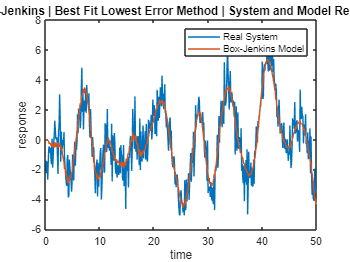


%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','Box-Jenkins Model')
title(" Box-Jenkins | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

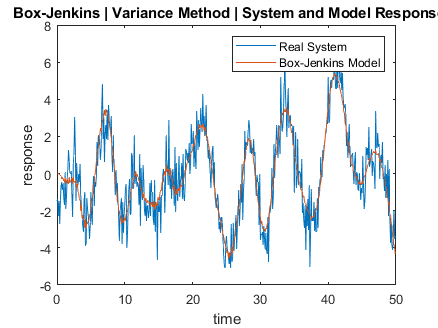


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','Box-Jenkins Model')
title(" Box-Jenkins | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

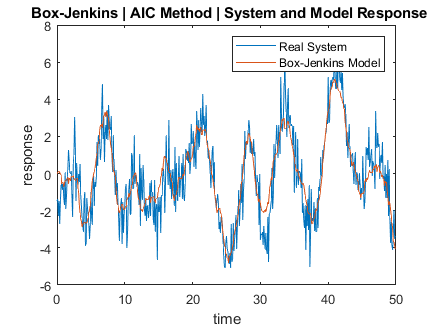


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','Box-Jenkins Model')
title(" Box-Jenkins | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

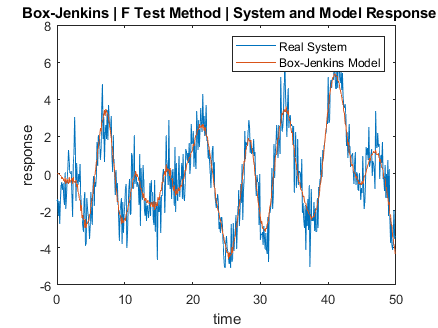


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','Box-Jenkins Model')
title(" Box-Jenkins | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

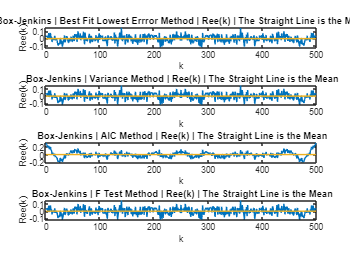


%%

figure(5)
subplot(4,1,1)
plot(1:N-1,bj_BestFit_Ree(2:end), 1:N-1, mean(bj_BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,2)
plot(1:N-1,bj_Var_Ree(2:end), 1:N-1, mean(bj_Var_Ree(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,3)
plot(1:N-1,bj_AIC_Ree(2:end), 1:N-1, mean(bj_AIC_Ree(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(4,1,4)
plot(1:N-1,bj_FTest_Ree(2:end), 1:N-1, mean(bj_FTest_Ree(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

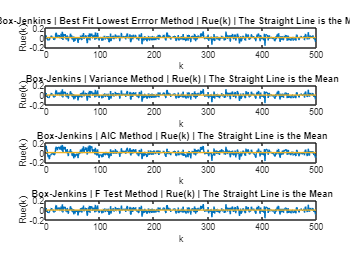


%%

figure(6)
subplot(4,1,1)
plot(1:N-1,bj_BestFit_Rue(2:end), 1:N-1, mean(bj_BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,2)
plot(1:N-1,bj_Var_Rue(2:end), 1:N-1, mean(bj_Var_Rue(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,3)
plot(1:N-1,bj_AIC_Rue(2:end), 1:N-1, mean(bj_AIC_Rue(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(4,1,4)
plot(1:N-1,bj_FTest_Rue(2:end), 1:N-1, mean(bj_FTest_Rue(2:end))*ones(length(1:N-1)))
title(" Box-Jenkins | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")